clear;
clc;

global currentState cumulatedState historicCurrentState historicCumulatedState GDP numberOfRefugees totalDeaths listOfCountries GDPBetween useNonLinModel startingVector;

## Parameters

% Choose whether results are to be (re)calculated during run
% Setting to false may be useful e.g. in order to only plot results
calculateResults = false;

% true - nonlinear fitting method (nonlinear regression)
% false - logarithmic fitting method (linear regression)
useNonLinModel = false;

% Choose whether to plot results at the end
plotResults = true;

% Time span in which historic data about cumulated number of refugees are to be calculated.
% The only historic data show how many refugees came to each country each year.
% As model is based on total refugees currently present in the country,
% It is crucial to "sum up" number of refugees at least up to the year in which
% a fitting or simulation is started
cumulatingStartYear = 2000;
cumulatingEndYear = 2015;

% Time span in which to train a model
learningStartYear = 2012;
learningEndYear = 2015;

% Time span in which to simulate refugee movement
simulationStartYear = 2012;
simulationEndYear = 2015;

% starting vector used only for nonlinear regression
if useNonLinModel
    startingVector = [1e-3, 2, 0.8, 0.2];
end

## Main program

if calculateResults
    % Load all used datasets from filed
    loadData();
    
    % Calculate historic data about number of refugees coming to countries each year
    % and cumulated number of refugees present in these countries in a particular year
    historicCumulatedState = calculateCumulatedNumberOfRefugeesFromYearToYear(cumulatingStartYear, cumulatingEndYear);
    historicCurrentState = getHistoricCurrentStateFromYearToYear(simulationStartYear, simulationEndYear);
    
    % Learning model
    model = learnModel(learningStartYear, learningEndYear);
    
    % Getting leqarned coefficients from model
    v = model.Coefficients.Estimate;
    
    % Applying learned coefficients to simulate refugee movement
    [currentState, cumulatedState] =  simulateRefugeeMovement(v, simulationStartYear, simulationEndYear);
end

## Plotting

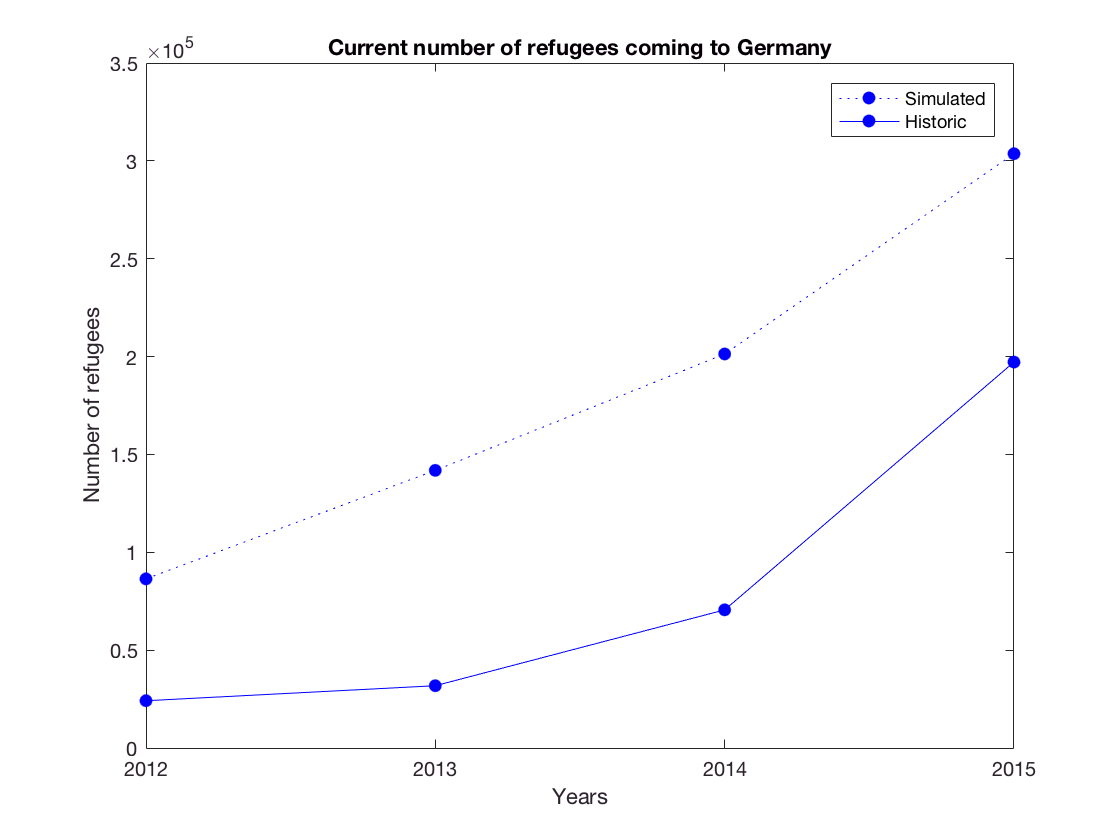

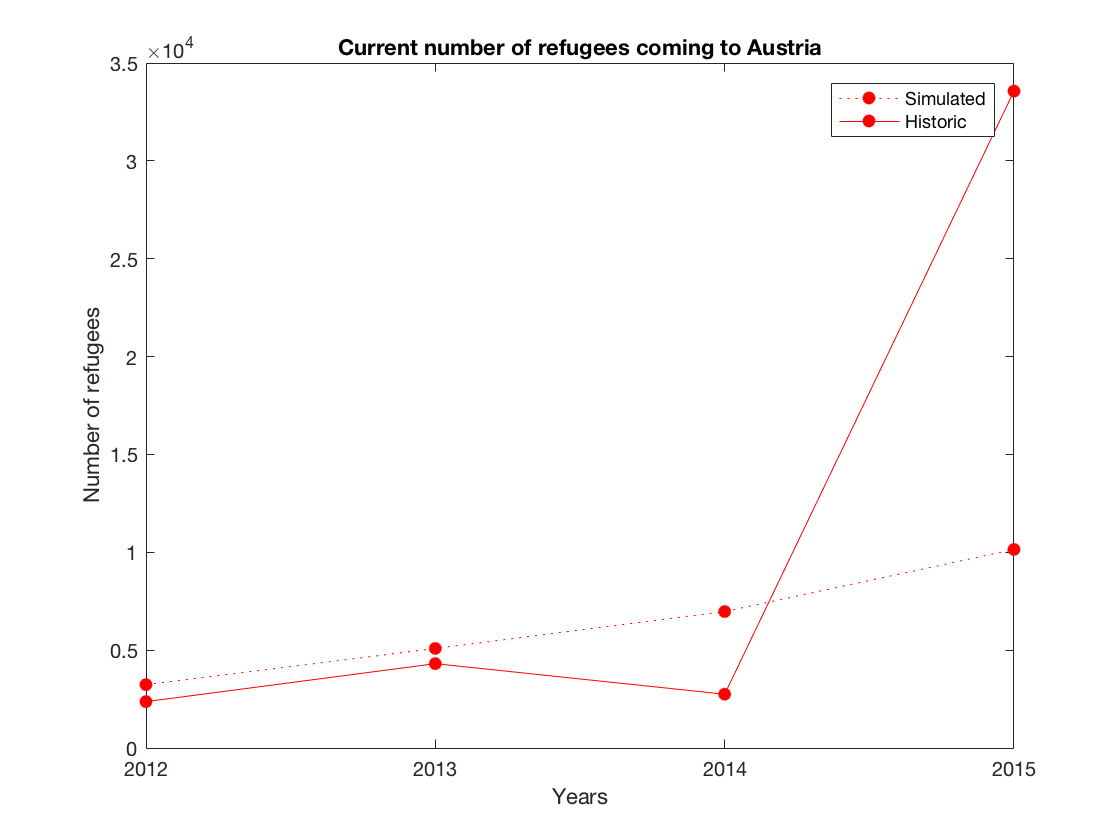

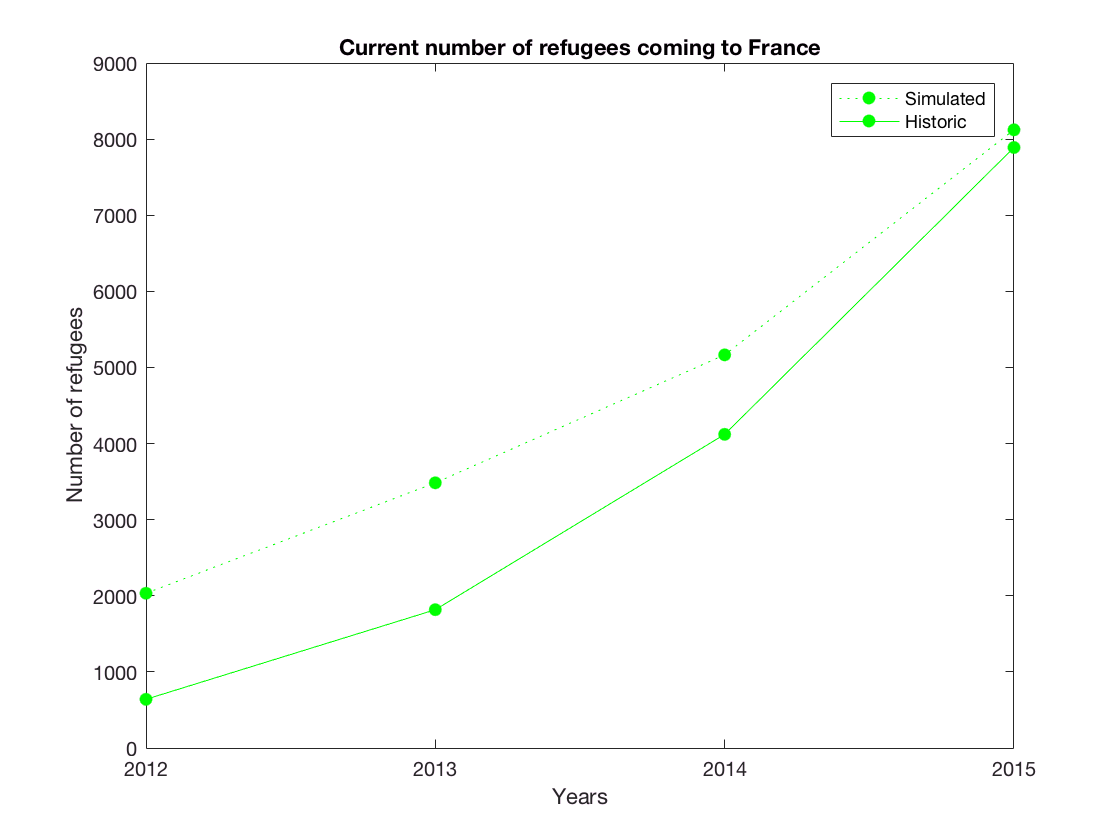

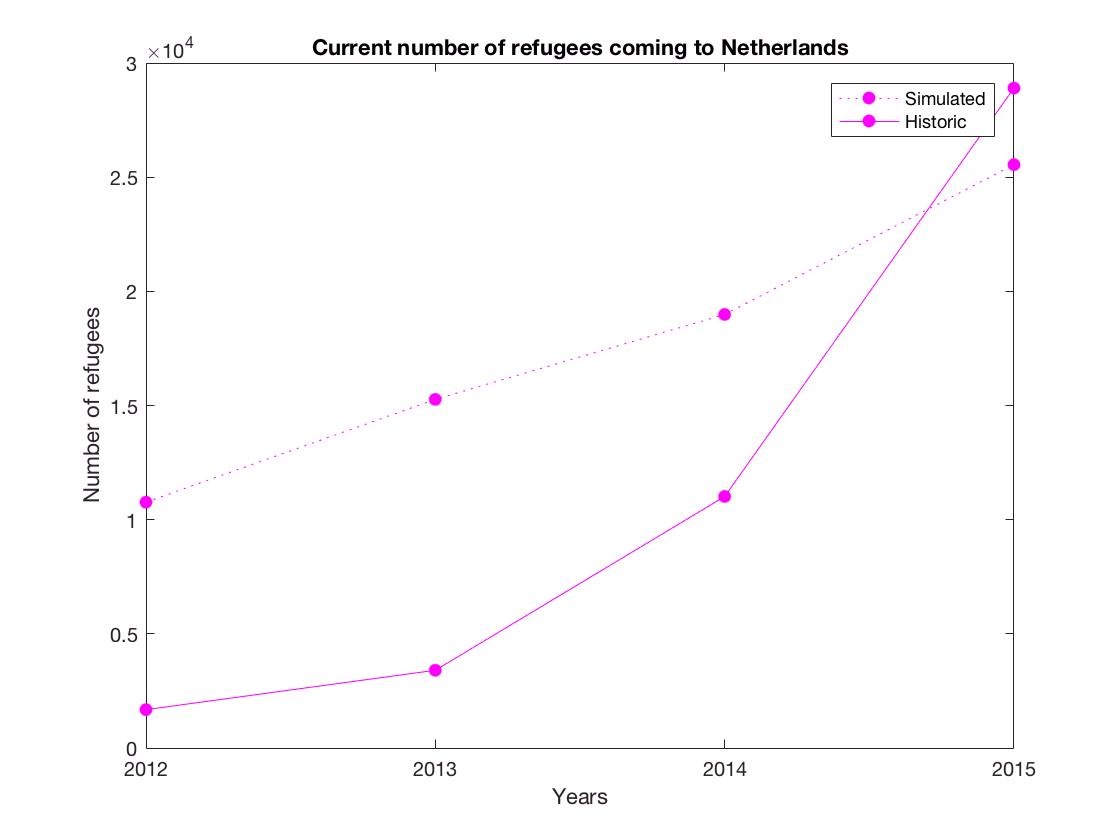

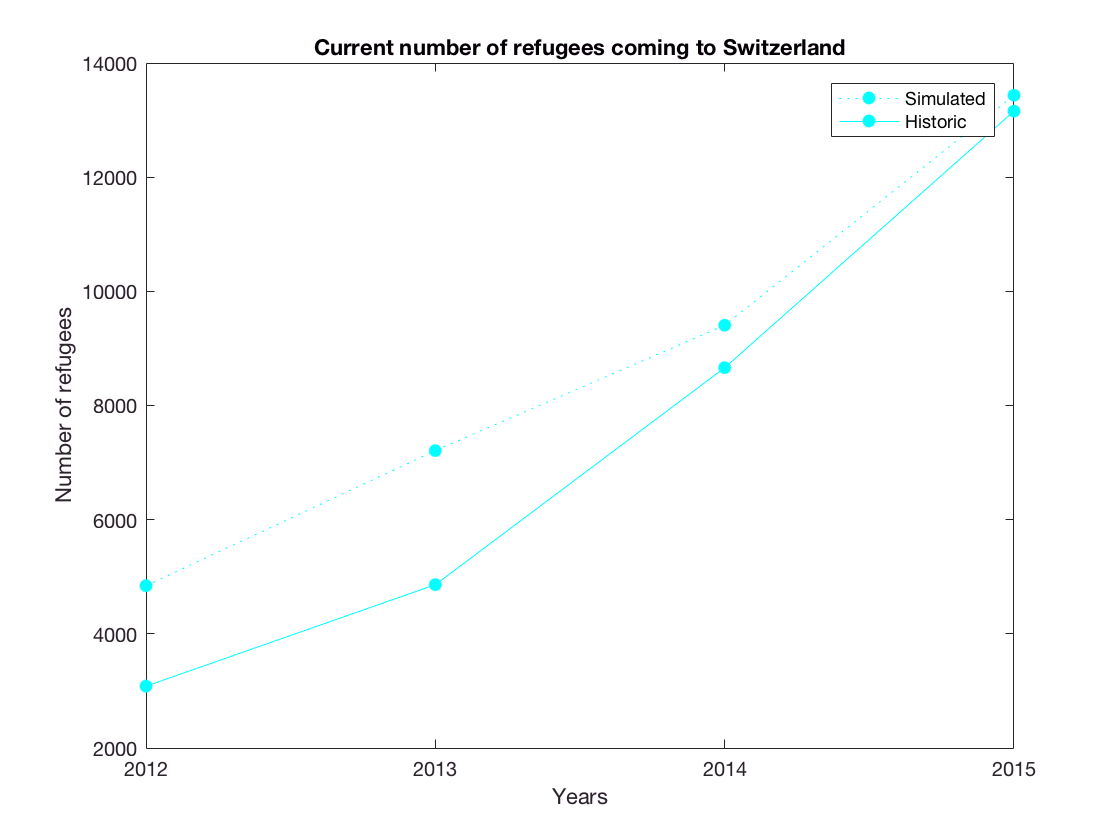

if plotResults
    close all;
    figure;
    plotHistoriAandSimulatedStateForCountry({'Germany'}, 'blue');
    figure;
    plotHistoriAandSimulatedStateForCountry({'Austria'}, 'red');
    figure;
    plotHistoriAandSimulatedStateForCountry({'France'}, 'green');
    figure;
    plotHistoriAandSimulatedStateForCountry({'Netherlands'}, 'magenta');
    figure;
    plotHistoriAandSimulatedStateForCountry({'Switzerland'}, 'cyan');
end

## Functions to visualize data

function plotHistoriAandSimulatedStateForCountry(country, color)
    global currentState historicCurrentState;
    years = [currentState(:).Year];
    plotCurrentY = [currentState(:).(country{1});];
    plotHistoricY = [historicCurrentState(:).(country{1})];
    plot(years, plotCurrentY, ':', 'Marker', '.', 'MarkerSize', 20, 'Color', color);
    hold on;
    plot(years, plotHistoricY, 'Marker', '.', 'MarkerSize', 20, 'Color', color);
    hold off;
    ax = gca;
    ax.XTick = years;
    title(['Current number of refugees coming to ', country{1}]);
    xlabel('Years');
    ylabel('Number of refugees');
    legend('Simulated', 'Historic');
end

## Simulation functions

function result = calculateNumberOfRefugees(b, x)
    global useNonLinModel;
    if useNonLinModel
        result = b(1).*x(:,1).*x(:,2).^b(2)./(x(:,3).^b(3).*x(:,4).^b(4));
    else
        result = exp(b(1)) * x(:,1)^b(2) * x(:,2)^b(3) * x(:,3)^b(4) * x(:,4)^b(5);
    end
end

function model = learnModel(startYear, endYear)
    
    global listOfCountries useNonLinModel startingVector;
    
    listOfYears = startYear:endYear;
    numberOfYears = length(listOfYears);
    numberOfCountries = length(listOfCountries);
    
    for i = 1:numberOfYears
        year = listOfYears(i);
        
        for j = 1:numberOfCountries
            country = listOfCountries(j);
            
            total_deaths = getTotalDeathsInSyriaInYear(year);
            GDP_of_country = getGDPOfCountryInYear(country, year);
            GDP_between = getGDPBetweenOfCountryInYear(country, year);
            previous_number_of_refugees = getHistoricCumulatedNumberOfRefugeesInCountryInYear(country, year-1);
            
            historic_number_of_refugees = getHistoricNumberOfRefugeesInCountryInYear(country, year);
            
            row_index = (i-1)*numberOfCountries+j;
            
            if useNonLinModel
                X(row_index,1:4) = [total_deaths, GDP_of_country, GDP_between, previous_number_of_refugees];
                y(row_index, 1) = historic_number_of_refugees;
            else
                X(row_index,1:4) = log([total_deaths, GDP_of_country, GDP_between, previous_number_of_refugees]);
                y(row_index, 1) = log(historic_number_of_refugees);
            end
        end
    
    end
    
    if useNonLinModel
        model = fitnlm(X, y, @calculateNumberOfRefugees, startingVector);
    else
        model = fitlm(X, y);
    end
    
end

function [currentState, cumulatedState] =  simulateRefugeeMovement(v, startYear, endYear)
    
    global listOfCountries;
    
    listOfYears = startYear:endYear;
    numberOfYears = length(listOfYears);
    numberOfCountries = length(listOfCountries);
    
    fields = ['Year'; listOfCountries];
    currentState = num2cell(zeros(1,numberOfCountries+1));
    currentState = cell2struct(currentState, fields, 2);
    
    cumulatedState = currentState;
    
    for i = 1:numberOfYears
        
        
        year = listOfYears(i);
        currentState(i).Year = year;
        cumulatedState(i).Year = year;
        
        for j = 1:numberOfCountries
            country = listOfCountries(j);
            
            total_deaths = getTotalDeathsInSyriaInYear(year);
            GDP_of_country = getGDPOfCountryInYear(country, year);
            GDP_between = getGDPBetweenOfCountryInYear(country, year);
            
            % During first iteration take historic data about cumulated number of refugees
            % In next steps take value calculated in a previous iteration
            if i < 2
                previous_number_of_refugees = getHistoricCumulatedNumberOfRefugeesInCountryInYear(country, year-1);
            else
                previous_number_of_refugees = cumulatedState(i-1).(country{1});
%                 previous_number_of_refugees = getCumulatedNumberOfRefugeesInCountryInYear(country, year-1);
            end
            
            x = [total_deaths, GDP_of_country, GDP_between, previous_number_of_refugees];
            calculatedNumberOfRefugees = calculateNumberOfRefugees(v, x);
            calculatedNumberOfRefugees = floor(calculatedNumberOfRefugees);
            
            currentState(i).(country{1}) = calculatedNumberOfRefugees;
            if i < 2
                cumulatedState(i).(country{1}) = getHistoricCumulatedNumberOfRefugeesInCountryInYear(country, year-1) + calculatedNumberOfRefugees;
            else
                cumulatedState(i).(country{1}) = cumulatedState(i-1).(country{1}) + calculatedNumberOfRefugees;
            end
            
        end

    end
    
end

## Functions to get needed data from available datasets

function result = getTotalNumberOfRefugeesInYear(year)
    global numberOfRefugees;
    index = strcmp({numberOfRefugees.Year}, string(year))==1;
    
    if sum(index) > 0
        a = {numberOfRefugees(index).Count};
        if ~isempty(a)
            m = str2double(a);
            result = sum(m);
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getHistoricCurrentStateFromYearToYear(startYear, endYear)
    
    global listOfCountries;
    listOfYears = startYear:endYear;
    numberOfYears = length(listOfYears);
    numberOfCountries = length(listOfCountries);
    
    historicCurrentState = num2cell(zeros(1,numberOfCountries));
    historicCurrentState = [startYear, historicCurrentState];
    fields = ['Year'; listOfCountries];
    historicCurrentState = cell2struct(historicCurrentState, fields, 2);
    
    for i = 1:numberOfYears
        year = listOfYears(i);
        historicCurrentState(i).Year = year;
        for j = 1:numberOfCountries
            country = listOfCountries(j);
            historicCurrentState(i).(country{1}) = getHistoricNumberOfRefugeesInCountryInYear(country, year);
        end
    end
    
    result = historicCurrentState;
end

function result = getHistoricNumberOfRefugeesInCountryInYear(country, year)
    global numberOfRefugees;
    index = strcmp({numberOfRefugees.Year}, string(year))==1 & strcmp({numberOfRefugees.Country}, country)==1;
    
    if sum(index) > 0
        a = str2double(numberOfRefugees(index).Count);
        if a > 0
            result = a;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getTotalDeathsInSyriaInYear(year)
    global totalDeaths;
    index = strcmp({totalDeaths.Year}, string(year))==1;
    
    if sum(index) > 0
        a = str2double(totalDeaths(index).Count);
        if a > 0
            result = a;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getGDPOfCountryInYear(country, year)
    global GDP;
    index = strcmp({GDP.Year}, string(year))==1;
    if sum(index) > 0
        a = str2double(GDP(index).(country{1}));
        if a > 0
            result = a;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getGDPBetweenOfCountryInYear(country, year)
    global GDPBetween;
    index = strcmp({GDPBetween.Year}, string(year))==1;
    
    if sum(index) > 0
        a = str2double(GDPBetween(index).(country{1}));
        if a > 0
            result = a;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = calculateCumulatedNumberOfRefugeesFromYearToYear(startYear, endYear)
    
    global listOfCountries;
    listOfYears = startYear:endYear;
    numberOfYears = length(listOfYears);
    numberOfCountries = length(listOfCountries);
    
    cumulatedState = num2cell(zeros(1,numberOfCountries));
    cumulatedState = [startYear, cumulatedState];
    fields = ['Year'; listOfCountries];
    cumulatedState = cell2struct(cumulatedState, fields, 2);
    
    for i = 1:numberOfYears
        year = listOfYears(i);
        cumulatedState(i).Year = year;
        for j = 1:numberOfCountries
            country = listOfCountries(j);
            if i < 2
                cumulatedState(i).(country{1}) = getHistoricNumberOfRefugeesInCountryInYear(country, year);
            else
                cumulatedState(i).(country{1}) = cumulatedState(i-1).(country{1}) + getHistoricNumberOfRefugeesInCountryInYear(country, year);
            end
        end
    end
    
    result = cumulatedState;
end

function result = getCumulatedNumberOfRefugeesInCountryInYear(country, year)
    
    global cumulatedState;
    a = {cumulatedState.Year};
    index = find([a{:}] == year);
    
    if ~isempty(index)
        number = cumulatedState(index).(country{1});
        if number > 0
            result = number;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

function result = getHistoricCumulatedNumberOfRefugeesInCountryInYear(country, year)
    
    global historicCumulatedState;
    a = {historicCumulatedState.Year};
    index = find([a{:}] == year);
    
    if ~isempty(index)
        number = historicCumulatedState(index).(country{1});
        if number > 0
            result = number;
        else
            result = 1;
        end
    else
        result = 1;
    end
end

## Loading all needed datasets

function loadData()
    
    global GDP numberOfRefugees totalDeaths GDPBetween listOfCountries;
    
    fileName = 'GDP_Europe_2010-2016.csv';
    GDP = importDataFile(fileName, ';');
    
    fileName = 'Syrian_Refugees_1980-2015_toEU.csv';
    numberOfRefugees = importDataFile(fileName, ';');
    
    fileName = 'Total_deaths_Syria_2008-2015.csv';
    totalDeaths = importDataFile(fileName, ';');
    
    fileName = 'gdp_between.csv';
    GDPBetween = importDataFile(fileName, ';');
    
    GDPfields = fieldnames(GDP);
    GDBBetweenFields = fieldnames(GDPBetween);
    GDPListOfCountries = unique(GDPfields(2:end)); % remove 'Year' field
    GDPBetweenListOfCountries = unique(GDBBetweenFields(2:end));
    DataListOfCountries = unique({numberOfRefugees(:).Country});
    listOfCountries = intersect(GDPListOfCountries, GDPBetweenListOfCountries);
    listOfCountries = intersect(listOfCountries, DataListOfCountries);
    
    GDPMissingCountries = setdiff(GDPListOfCountries, listOfCountries);
    GDP = rmfield(GDP, GDPMissingCountries);
    
    GDPBetweenMissingCountries = setdiff(GDPBetweenListOfCountries, listOfCountries);
    GDPBetween = rmfield(GDPBetween, GDPBetweenMissingCountries);
    
    % Sorting countries alphabetically
    fields = ['Year'; listOfCountries];
    
    GDP = orderfields(GDP, fields);
    GDPBetween = orderfields(GDPBetween, fields);
    
end

## Importing data from one file

function dataStruct = importDataFile(fileName, delimiter)

    dataDirectory = '../doc/data/';
    filePath = strcat(dataDirectory, fileName);
    fileID = fopen(filePath);
    tline = fgetl(fileID);
    nColumns = length(find(tline==delimiter))+1;
    
    frewind(fileID);
    
    field = textscan(fileID, repmat('%s', 1, nColumns), 1, 'Delimiter', delimiter);
    field = horzcat(field{:});
    value = textscan(fileID, repmat('%s', 1, nColumns), 'Delimiter', delimiter);
    value = horzcat(value{:});
    
    dataStruct = cell2struct(value, field, 2);

end